# Locate and Display Peaks in Hough Transform of Rotated Image

Read image into workspace.

I  = imread('circuit.tif');

Create binary image.

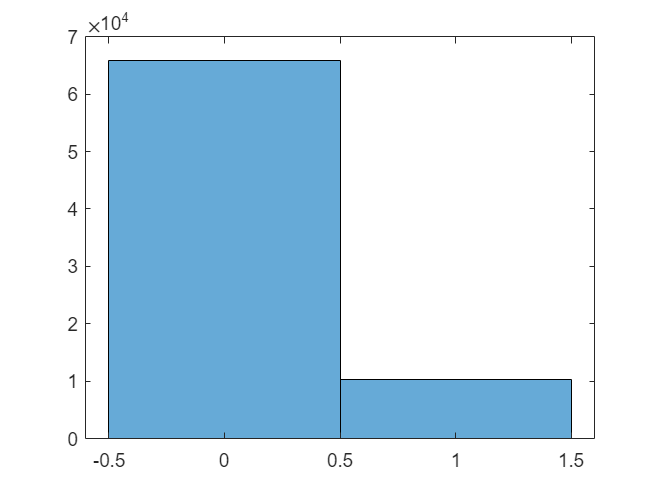

BW = edge(imrotate(I,50,'crop'),'canny');
histogram(BW);

Create Hough transform of image.

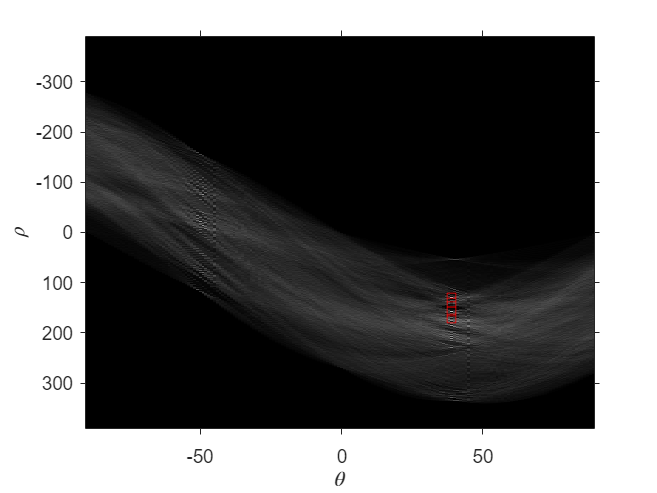

[H,T,R] = hough(BW);
% H % Hough 变换矩阵
% find peaks in the Hough transform of the image and plot them.
P  = houghpeaks(H,4, "Threshold",0.9);
imshow(H,[],'XData',T,'YData',R,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
plot(T(P(:,2)),R(P(:,1)),'s','color','red');

*Copyright 2015 The MathWorks, Inc.*